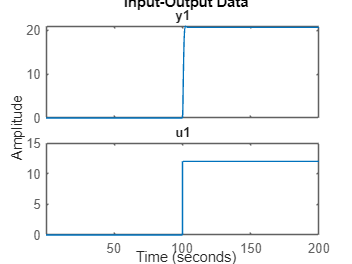


% ============================================================
%     MENG 3020 – FINAL PROJECT – PART B (Grey-box Modelling)
%     Robot Arm-Link System Modeling & Identification
% ============================================================
% Dataset 17 below
B=4.559616926738720;
Bm=0.007052058673279;
g=9.810000000000000;
JG1=0.006991571816190;
JG2=0.099652027026338;
Jm=0.005574135299072;
Js1=0.046073254839203;
Js2=0.021931365993199;
Kb=0.877543876952904;
KT=0.877543876952904;
L=0.227699523910398;
La=0.078730828169049;
m=4.005658359474392;
N=5;
Ra=16.692387716797505;
Ts=0.050000000000000;
% =============================
% LOAD SIMULINK OUTPUT DATA
% =============================
ang = out.angle;
volt = out.voltage;

angN = out.angleN;
voltN = out.voltageN;

% =============================
% CREATE IDDATA OBJECT
% =============================
data_step = iddata(ang, volt, Ts);
plot(data_step);


sys_step = tfest(data_step, 2, 1);
present(sys_step);

                                                                                                                                                                                                                                                                                                                   
sys_step_step =                                                                                                                                                                                                                                                                                                    
                                                                                                                                                                                                                                                                                                                   
  From input "u1" to output "y1":                                           

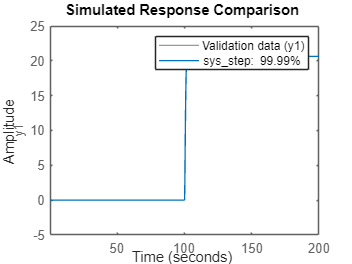

compare(data_step, sys_step);

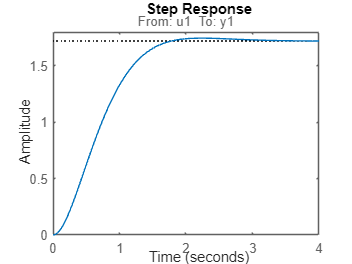


stepplot(sys_step)

stepinfo(sys_step)

ans = struct with fields:
         RiseTime: 1.0505
    TransientTime: 1.6051
     SettlingTime: 1.6051
      SettlingMin: 1.5589
      SettlingMax: 1.7455
        Overshoot: 1.4684
       Undershoot: 0
             Peak: 1.7455
         PeakTime: 2.2405


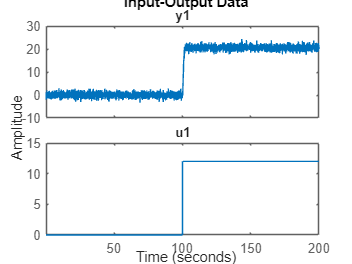


data_stepN = iddata(angN, voltN, Ts);
plot(data_stepN);


sys_stepN = tfest(data_stepN, 2, 1);
present(sys_stepN);

                                                                                                                                                                                                                                                                                                                        
sys_stepN_stepN =                                                                                                                                                                                                                                                                                                       
                                                                                                                                                                                                                                                                                                                        
  From input "u1" to output "y1":                            

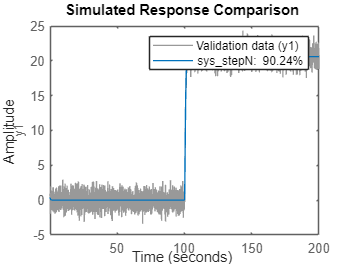

compare(data_stepN, sys_stepN);

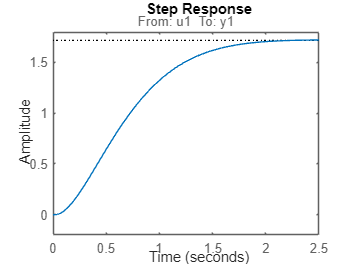


stepplot(sys_stepN)

stepinfo(sys_stepN)

ans = struct with fields:
         RiseTime: 1.1002
    TransientTime: 1.7928
     SettlingTime: 1.7930
      SettlingMin: 1.5530
      SettlingMax: 1.7218
        Overshoot: 0.2376
       Undershoot: 0.0741
             Peak: 1.7218
         PeakTime: 2.6681


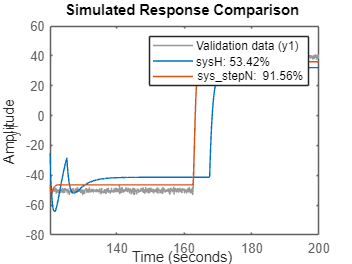

compare(dataVAL_High, sysH, sys_stepN)

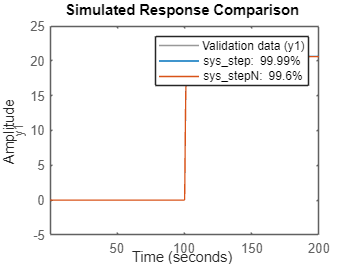

compare(data_step, sys_step, sys_stepN)


% =============================
% END OF PART B
% =============================